### **Método de Newton-Raphson**** (Tangentes)**


$$x^{k+1} = x^{k}-\frac{f(x^{k})}{f'(x^{k})}$$


Vamos encontrar o zero da função $f(x) = -0.5x^{2}+2.5x+4.5$ no intervalo de $[-2.5,0]$utilizando o método de Newton-Raphson, com  chute inicial $x^{0} = -1$ e **erro relativo** igual ou menor que $10^{-4}$.

erro relativo:


$$er = \frac {|x^{k+1}-x^{k}|} {|x^{k+1}|}$$


**Graficamente, **

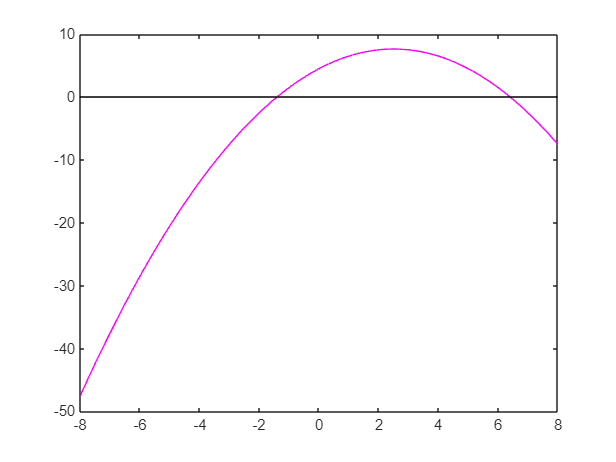

x= -8:0.01:8;
y = fun(x);
plot(x,y,'magenta')
y1 = 0*x;
hold on 
plot(x,y1, 'black')
hold off

**Implementação do Newton-Raphson:**

format long
%Chute inicial
x0 = -1;
fx0 = fun(x0);
tol = 10^-4;
k = 0;
er = 2;
while(er > tol)
    x = x0 - (fun(x0)/dfun(x0)); %atualizando o zero da função usando o metodo de newton-raphson
    er = abs(x-x0)/abs(x);%calculando erro relativo
    x0 = x;
    fx0 = fun(x0);
    k = k+1;
    xk(k,:) = x0;
    fk(k,:) = fx0;
    erk(k,:) = er;
end
[xk,fk, erk]

ans =   -1.428571428571429  -0.091836734693878   0.300000000000000
  -1.405194805194805  -0.000273233260246   0.016635859519409
  -1.405124838580110  -0.000000002447663   0.000049793877935


**Definindo as funções que serão utilizadas:**

function f1 = fun(x)
    f1 = -0.5*x.^2 +2.5*x + 4.5;
end
function g1 = dfun(x)
    g1 = -x + 2.5;
end
